# Modulation Classification - Trained Network

Modulation identification is an important function for an intelligent receiver. It has numerous applications in cognitive radar, software-defined radio, and efficient spectrum management. 

In this exercise, you will explore a pretrained deep learning network and see how it classifies 6 different modulations. 

*Copyright 2022 The MathWorks, Inc.*

## Are You in the Correct Directory?

% Run this to check proper configuration 

% Start from a clean workspace
clearvars

if isfolder('1-HelperFiles')
    disp('You are in the correct directory. Please continue.')
    addpath('1-HelperFiles')
   
else  
    error('Please navigate to the proper Directory')
end

You are in the correct directory. Please continue.


## Load Pre-trained CNN

load modPredNetwork.mat

## Inspect the Network

% Inspect network's layers
net.Layers

ans =   8×1 Layer array with layers:

     1   'imageinput'    Image Input             1×1024×2 images with 'zerocenter' normalization
     2   'conv'          Convolution             16 1×8×2 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'batchnorm'     Batch Normalization     Batch normalization with 16 channels
     4   'relu'          ReLU                    ReLU
     5   'maxpool'       Max Pooling             1×2 max pooling with stride [1  2] and padding [0  0  0  0]
     6   'fc'            Fully Connected         6 fully connected layer
     7   'softmax'       Softmax                 softmax
     8   'classoutput'   Classification Output   crossentropyex with '16QAM' and 5 other classes

% Inspect the different classes available by observing the last layer in the network
classes = net.Layers(end).ClassNames

classes = 6×1 cell array
    {'16QAM'}
    {'64QAM'}
    {'BPSK' }
    {'GFSK' }
    {'PAM4' }
    {'QPSK' }


## Classify Modulations 

The trained network takes in frames impaired with Rician multipath fading, center frequency offset,  sampling time drift, and AWGN and predicts the modulation type. 

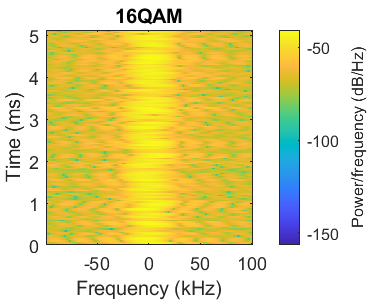

% Select a modulation type 
modType = "16QAM"; 

% Select a random frame of the modulation type and plot its spectrogram 
modFrame = hSelectTestFrame(rxFrames,rxLabels,modType);

% Feed the frame into the network for classification
predModType = classify(net,modFrame)

predModType = categorical
     16QAM 


## Observation

Is the network accurate all the time? Are there any modulation types that are being confused by  the network? 

Answers in Exercise 2! 